# Trabalho Computacional 2 de Sistemas Realimentados

### Componentes do grupo: Amanda S. Bassani e João Paulo B. da Rocha

## 1.0 Inicialização

close all
clear all
clc
N = 11;

## 2.0 Projeto

A dinâmica do veiculo lunar (Sistemas de Controle Moderno 8ed. Dorf e Bishop. Capítulo 12 Sistemas de Controle Robusto. P12.10) é dada por:


$$G=\frac{100N}{\left(s+\left(25-N\right)\right)\left(s+\frac{25}{N}\right)}e^{-\textrm{Ts}}$$


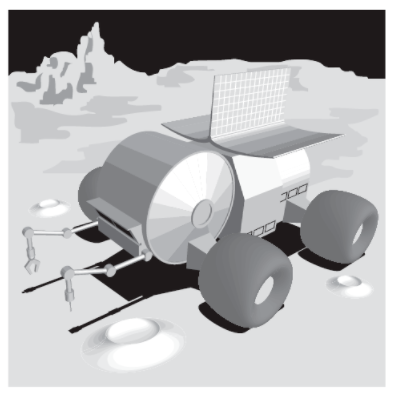

#### 2.1 Projetar controlador PID, considerando dois casos, com e sem atraso de transporte. Utilizando a resposta em frequência para que o sistema tenha as seguintes especificações:

- Erro ao degrau e ao distúrbio de degrau menores ou iguais a 0.1;

- Largura de banda FTMA maior possível;

- Margem de fase maior ou igual a 60º.

Caso 1. Sem atraso de transporte. T=0.

Caso 2. Com atraso de transporte. T=0.1/N.

### Caso 1: T=0

syms s

T = 0; %Caso 1: T=0 | Caso 2: T=0.1/N
np = 100*N;
dp = conv([1 25-N],[1 25/N]);
gp = tf(np,dp,'InputDelay',T) % sistema tipo zero, erro ao degrau é diferente de zero e com atraso T

gp =
 
          1100
  ---------------------
  s^2 + 16.27 s + 31.82
 
Continuous-time transfer function.



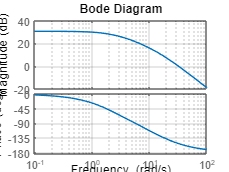


figure
w = logspace(-1,2);
bode(gp,w)
grid on


% 20*log(Kp) pelo gráfico de bode vale 30.8 dB. 

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
nps = poly2sym(np,s);
dps = poly2sym(dp,s);
gps = nps/dps;
    % Entrada degrau
sEs = 1/(1+gps);
ess = double(limit(sEs,s,0,'right'))

ess = 0.0281

    % Disturbio degrau
sEd = gps/(1+gps);
essd = double(limit(sEd,s,0,'right'))

essd = 0.9719

%-------------------------------------------------------------------------------------------------

Com o aumento de K, diminui o erro em regime a entrada e a margem de fase. O erro a entrada degrau da planta atende as especificações, então qualquer valor escolhido para Kp do PI vai atender também.

#### Etapa 1: Calcular MG, MF e LB

[Gm,Pm,Wgm,Wpm]=margin(gp)

Gm = Inf

Pm = 27.9459

Wgm = Inf

Wpm = 31.6788

%MF de gp = 27.95 e largura de banda = 31.68


#### Etapa 2: Nova frequência de cruzamento de ganho

FaseGp = 25 - 180

FaseGp = -155

Olhando no gráfico de bode, a nova frequencia de cruzamento de ganho (w_0dB) deve ser 36.1 rad/s e o módulo nessa frequência é -2.12

#### Etapa 3: Calcular o ganho proporcional do PI (K_P) 

% de maneira que G_MA=G_P×K_P tenha a margem de fase PM proximo de 25 graus na  nova 
% frequência de cruzamento de ganho (w_0dB).
syms kpi
eq = 20*log10(kpi)-2.12;
kpi = double(solve(eq))

kpi = 1.2764

% kpi encontrado foi de 1.2764
gma=gp*kpi;
[Gma,Pma,Wgma,Wpma]=margin(gma)

Gma = Inf

Pma = 24.7683

Wgma = Inf

Wpma = 36.1488

gmf = feedback(gma,1);
% A margem de fase obtida foi de 24.77.

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
    % Entrada degrau
sEs = 1/(1+gps);
ess(1) = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+kpi*gps);
essd(1) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

#### Etapa 4: Escolher a frequência de corte do PI

% tal que o atraso de fase do PI ocorra um pouco abaixo da nova frequência de cruzamento de ganho.
% Em seguida, simular o PI com a planta, e verificar se a resposta é estável e rápida.

kii=kpi*Wpma/5;
pi=tf([kpi kii],[1 0])

pi =
 
  1.276 s + 9.228
  ---------------
         s
 
Continuous-time transfer function.



ggma=gp*pi;
[Gm,Pm,Wgm,Wpm]=margin(ggma)

Gm = Inf

Pm = 13.3366

Wgm = Inf

Wpm = 36.5229

%MF= 13.33 e LB=36.52 com PI
ggmf=feedback(ggma,1);
t=0.0:0.01:7;
y1=step(ggmf,t);
%step(ggmf); %resposta ao degrau
stepinfo(y1,t) % É rapida e estável

ans = struct with fields:
         RiseTime: 0.0304
    TransientTime: 0.8690
     SettlingTime: 0.8690
      SettlingMin: 0.5269
      SettlingMax: 1.7043
        Overshoot: 70.4252
       Undershoot: 0
             Peak: 1.7043
         PeakTime: 0.0900



%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
pis = (kpi*s + kii)/s;

    % Entrada degrau
sEs = 1/(1+pis*gps);
ess(2) = double(limit(sEs,s,0,'right'));

    % Disturbio degrau
sEd = gps/(1+pis*gps);
essd(2) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

#### Etapa 5: Projetar PD > 1+sKdd

kdd=1/Wpma;
npid=conv([kpi kii],[kdd 1]);
dpid=[1 0];
pid=tf(npid,dpid)

pid =
 
  0.03531 s^2 + 1.532 s + 9.228
  -----------------------------
                s
 
Continuous-time transfer function.



gggma=gp*pid

gggma =
 
  38.84 s^2 + 1685 s + 1.015e04
  -----------------------------
    s^3 + 16.27 s^2 + 31.82 s
 
Continuous-time transfer function.



[Gm,Pm,Wgm,Wpm]=margin(gggma)

Gm = Inf

Pm = 63.1787

Wgm = NaN

Wpm = 47.3504

gggmf=feedback(gggma,1);
y2=step(gggmf,t);
stepinfo(y2,t);

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
npids = poly2sym(npid,s);
dpids = poly2sym(dpid,s);
pids = npids/dpids;

    % Entrada degrau
sEs = 1/(1+pids*gps);
ess(3) = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+pids*gps);
essd(3) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

% Reprojetando o PD
kdd=5/Wpma;
npid=conv([kpi kii],[kdd 1]);
dpid=[1 0];
pid=tf(npid,dpid)

pid =
 
  0.1766 s^2 + 2.553 s + 9.228
  ----------------------------
               s
 
Continuous-time transfer function.



gc6 = pid;          %controlador utilizado na questão 2.6 - Armazenada em nova variável
gggma2=gp*pid

gggma2 =
 
  194.2 s^2 + 2808 s + 1.015e04
  -----------------------------
    s^3 + 16.27 s^2 + 31.82 s
 
Continuous-time transfer function.



[Gm,Pm,Wgm,Wpm]=margin(gggma2)

Gm = Inf

Pm = 90.5304

Wgm = NaN

Wpm = 193.9604

gggmf2=feedback(gggma2,1);
y3=step(gggmf2,t);
stepinfo(gggmf2)

ans = struct with fields:
         RiseTime: 0.0116
    TransientTime: 0.0220
     SettlingTime: 0.0220
      SettlingMin: 0.9010
      SettlingMax: 0.9989
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9989
         PeakTime: 0.0558


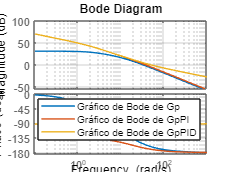

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
npids = poly2sym(npid,s);
dpids = poly2sym(dpid,s);
pids = npids/dpids;

    % Entrada degrau
sEs = 1/(1+pids*gps);
ess(4) = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+pids*gps);
essd(4) = double(limit(sEd,s,0,'right'));
%-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-
% Plots

figure
hold on
bode(gp);
bode(ggma);
bode(gggma);
grid on
legend('Gráfico de Bode de Gp','Gráfico de Bode de GpPI', 'Gráfico de Bode de GpPID');

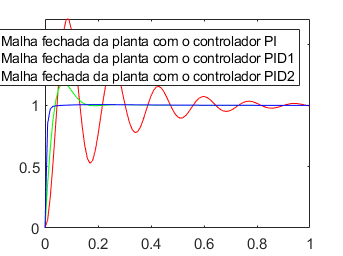

figure
plot(t,y1,'r',t,y2,'g',t,y3,'b')
axis([0 1 0 inf])
legend('Malha fechada da planta com o controlador PI','Malha fechada da planta com o controlador PID1','Malha fechada da planta com o controlador PID2' );


MG=0;MF=0;LB=0;OS=0;RT=0;ST=0;
[Gm,Pm,Wgm,Wpm]=margin(gma);
MG(1) = Gm;
MF(1) = Pm;
LB(1) = bandwidth(gmf);
OS(1)=stepinfo(gmf).Overshoot;
RT(1)=stepinfo(gmf).RiseTime;
ST(1)=stepinfo(gmf).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(ggma);
MG(2) = Gm;
MF(2) = Pm;
LB(2) = bandwidth(ggmf);
OS(2)=stepinfo(ggmf).Overshoot;
RT(2)=stepinfo(ggmf).RiseTime;
ST(2)=stepinfo(ggmf).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gggma);
MG(3) = Gm;
MF(3) = Pm;
LB(3) = bandwidth(gggmf);
OS(3)=stepinfo(gggmf).Overshoot;
RT(3)=stepinfo(gggmf).RiseTime;
ST(3)=stepinfo(gggmf).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gggma2);
MG(4) = Gm;
MF(4) = Pm;
LB(4) = bandwidth(gggmf2);
OS(4)=stepinfo(gggmf2).Overshoot;
RT(4)=stepinfo(gggmf2).RiseTime;
ST(4)=stepinfo(gggmf2).SettlingTime;


col_Kp = [OS(1) RT(1) ess(1) essd(1) MG(1) MF(1) LB(1)]';
col_PI = [OS(2) RT(2) ess(2) essd(2) MG(2) MF(2) LB(2)]';
col_PID1 = [OS(3) RT(3) ess(3) essd(3) MG(3) MF(3) LB(3)]';
col_PID2 = [OS(4) RT(4) ess(4) essd(4) MG(4) MF(4) LB(4)]';
col_PID_nodelay = col_PID2;
Tabela1=table(col_Kp,col_PI,col_PID1,col_PID2,'RowNames',{'Sobressinal (%)','T. Subida (s)','Erro à entrada degrau','Erro ao disturbio de degrau','MG','MF','LB'},'VariableNames',{'Gp*Kp','Gp*PI','Gp*PID1','Gp*PID2'})

Tabela1 = 7×4 table
                                    Gp*Kp       Gp*PI      Gp*PID1     Gp*PID2
                                   ________    ________    ________    _______

    Sobressinal (%)                  50.124      71.485       18.43         0 
    T. Subida (s)                  0.032332    0.030459    0.028551    0.0116 
    Erro à entrada degrau          0.028112           0           0         0 
    Erro ao disturbio de degrau     0.76607           0           0         0 
    MG                                  Inf         Inf         Inf       Inf 
    MF                               24.768      13.337      63.179     90.53 
    LB                               56.924      57.328      63.094    191.69 


### Caso 2: T=0.1/N

T = 0.1/N; %Caso 1: T=0 | Caso 2: T=0.1/N
np = 100*N;
dp = conv([1 25-N],[1 25/N]);
gpd = tf(np,dp,'InputDelay',T) % sistema tipo zero, erro ao degrau é diferente de zero e com atraso T

gpd =
 
                            1100
  exp(-0.00909*s) * ---------------------
                    s^2 + 16.27 s + 31.82
 
Continuous-time transfer function.



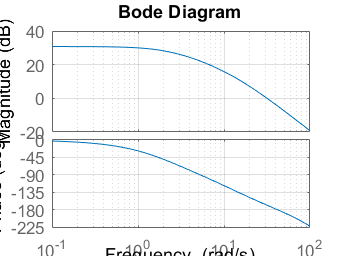

w = logspace(-1,2);
figure
bode(gpd,w)
grid on

% 20*log(Kp) pelo gráfico de bode vale 30.8 dB.

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
nps = poly2sym(np,s)*exp(-T*s);
dps = poly2sym(dp,s);
gps = nps/dps;
    % Entrada degrau
sEs = 1/(1+gps);
ess = double(limit(sEs,s,0,'right'))

ess = 0.0281

    % Disturbio degrau
sEd = gps/(1+gps);
essd = double(limit(sEd,s,0,'right'))

essd = 0.9719

%-------------------------------------------------------------------------------------------------

% O módulo não se altera, logo segue o modelo anterior.
% Kp = 10^(30.8/20)
% ess = 1/(Kp+1) % erro em regime ao degrau sistema tipo 0

Com o aumento de K, diminui o erro em regime a entrada e a margem de fase. O erro a entrada degrau da planta atende as especificações, então qualquer valor escolhido para Kp do PI vai atender também.

#### Etapa 1: Calcular MG, MF e LB

[Gm,Pm,Wgm,Wpm]=margin(gpd);
Pm

Pm = 11.4453

Wpm

Wpm = 31.6788

%MF de gp = 11.44 e largura de banda = 31.68


#### Etapa 2: Nova frequência de cruzamento de ganho

FaseGp = 25 - 180;
% Olhando no gráfico de bode, a nova frequencia de cruzamento de ganho (w_0dB)
% deve ser aproximadamente 24.4 rad/s e o módulo nessa frequência é 4.04


#### Etapa 3: Calcular o ganho proporcional do PI (K_P)

% de maneira que G_MA=G_P×K_Ptenha a margem de fase PM proximo de 25 graus 
% na  nova frequência de cruzamento de ganho (w_0dB).

syms kpi
eq = 20*log10(kpi)+4.04;
kpi = double(solve(eq))

kpi = 0.6281

gma=gpd*kpi;
[Gma,Pma,Wgma,Wpma]=margin(gma);

gmf = feedback(gma,1);
%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
    % Entrada degrau
sEs = 1/(1+gps);
ess(1) = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+kpi*gps);
essd(1) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

#### Etapa 4: Escolher a frequência de corte do PI

% tal que o atraso de fase do PI ocorra um pouco abaixo da nova frequência de cruzamento de ganho.
% Em seguida, simular o PI com a planta, e verificar se a resposta é estável e rápida.

kii=kpi*Wpma/5;
pi=tf([kpi kii],[1 0])

pi =
 
  0.6281 s + 3.069
  ----------------
         s
 
Continuous-time transfer function.



ggma=gpd*pi

ggma =
 
                         690.9 s + 3376
  exp(-0.00909*s) * -------------------------
                    s^3 + 16.27 s^2 + 31.82 s
 
Continuous-time transfer function.



[Gm,Pm,Wgm,Wpm]=margin(ggma)

Gm = 1.8271

Pm = 10.7464

Wgm = 34.3215

Wpm = 24.7003


ggmf=feedback(ggma,1);

t=0.0:0.01:7;
y1 = step(ggmf,t); % resposta ao degrau
stepinfo(y1,t) % É rapida e estável

ans = struct with fields:
         RiseTime: 0.0429
    TransientTime: 1.6313
     SettlingTime: 1.6313
      SettlingMin: 0.4439
      SettlingMax: 1.7846
        Overshoot: 78.4617
       Undershoot: 0
             Peak: 1.7846
         PeakTime: 0.1300



%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
pis = (kpi*s + kii)/s;

    % Entrada degrau
sEs = 1/(1+pis*gps);
ess(2) = double(limit(sEs,s,0,'right'));

    % Disturbio degrau
sEd = gps/(1+pis*gps);
essd(2) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

#### Etapa 5: Projetar PD > 1+sKdd

kdd=1/Wpma;
npid=conv([kpi kii],[kdd 1]);
dpid=[1 0];
pid=tf(npid,dpid);
gggma=gp*pid;
[Gm,Pm,Wgm,Wpm]=margin(gggma)

Gm = Inf

Pm = 71.9005

Wgm = NaN

Wpm = 32.7266

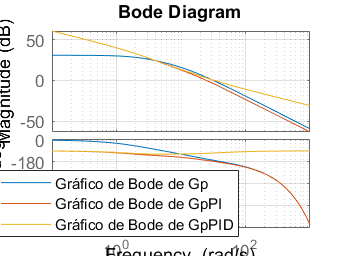


gggmf=feedback(gggma,1);
y2=step(gggmf,t);
stepinfo(y2,t);

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
npids = poly2sym(npid,s);
dpids = poly2sym(dpid,s);
pids = npids/dpids;

    % Entrada degrau
sEs = 1/(1+pids*gps);
ess(3) = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+pids*gps);
essd(3) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

%-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-
% Plots

figure
hold on
bode(gpd);
bode(ggma);
bode(gggma);
grid on
legend('Gráfico de Bode de Gp','Gráfico de Bode de GpPI', 'Gráfico de Bode de GpPID','Position',[0.17024,0.14517,0.34643,0.11905]);

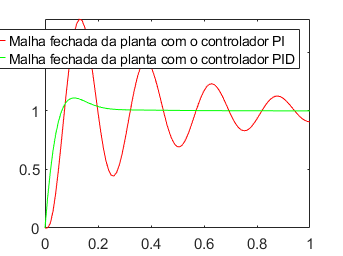

figure
plot(t,y1,'r',t,y2,'g')
axis([0 1 0 inf])
legend()
legend('Malha fechada da planta com o controlador PI','Malha fechada da planta com o controlador PID');


MG=0;MF=0;LB=0;OS=0;RT=0;ST=0;
[Gm,Pm,Wgm,Wpm]=margin(gma);
MG(1) = Gm;
MF(1) = Pm;
LB(1) = bandwidth(gmf);
OS(1)=stepinfo(gmf).Overshoot;
RT(1)=stepinfo(gmf).RiseTime;
ST(1)=stepinfo(gmf).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(ggma);
MG(2) = Gm;
MF(2) = Pm;
LB(2) = bandwidth(ggmf);
OS(2)=stepinfo(ggmf).Overshoot;
RT(2)=stepinfo(ggmf).RiseTime;
ST(2)=stepinfo(ggmf).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gggma);
MG(3) = Gm;
MF(3) = Pm;
LB(3) = bandwidth(gggmf);
OS(3)=stepinfo(gggmf).Overshoot;
RT(3)=stepinfo(gggmf).RiseTime;
ST(3)=stepinfo(gggmf).SettlingTime;


col_Kp = [OS(1) RT(1) ess(1) essd(1) MG(1) MF(1) LB(1)]';
col_PI = [OS(2) RT(2) ess(2) essd(2) MG(2) MF(2) LB(2)]';
col_PID = [OS(3) RT(3) ess(3) essd(3) MG(3) MF(3) LB(3)]';
Tabela1=table(col_Kp,col_PI,col_PID,'RowNames',{'Sobressinal (%)','T. Subida (s)','Erro à entrada degrau','Erro ao disturbio de degrau','MG','MF','LB'},'VariableNames',{'Gp*Kp','Gp*PI','Gp*PID'})

Tabela1 = 7×3 table
                                    Gp*Kp       Gp*PI       Gp*PID 
                                   ________    ________    ________

    Sobressinal (%)                  55.473      77.658      11.086
    T. Subida (s)                  0.045003    0.042563    0.046058
    Erro à entrada degrau          0.028112           0           0
    Erro ao disturbio de degrau      1.5221           0           0
    MG                               2.6539      1.8271         Inf
    MF                               22.405      10.746        71.9
    LB                                40.17      39.786      40.824


#### 2.2 Para o caso em que T=0 seg, multiplique o controlador projetado pela FT G do veículo lunar e determine a equação de estados deste sistema em malha aberta. Em seguida, desenvolva um código no matlab, semelhante ao fornecido para simular o avião (programa “simulaviao.m” fornecido em anexo), para simular o sistema de controle de direção do veículo lunar em malha fechada no espaço de estados. Considere nas simulações os seguintes casos:

#### Caso 1. Sistema de controle sem o ruído de medição.

Usando o Controlador PID:

Usando a função transferência de malha aberta encontrada no item 1.1 ao multiplicar o controlador PID1 pela planta:

num = [38.84 1685 10150];
den = [1 16.27 31.82 0];

gg2 = tf(num,den)

gg2 =
 
  38.84 s^2 + 1685 s + 10150
  --------------------------
  s^3 + 16.27 s^2 + 31.82 s
 
Continuous-time transfer function.



O que se espera após os passos que se seguem é obter uma curva nesse estilo:

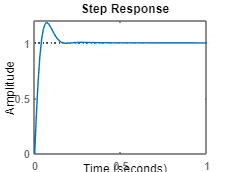

gg2f = feedback(gg2,1);
figure
t=0.0:0.01:1;
step(gg2f,t)

#### Utilizando o modelo de formato de entrada com ação à frente (feedforward):

Usando a função de malha aberta do controlador vezes a G da planta, identificamos seus coeficientes:


$$C(s)G_p(s) = \frac{38.84s^2+1685s+10150}{s^3+16,27s^2+31,82s}=\frac{b_2s^2+b_1s+b_0}{s^3+a_2s^2+a_1s}$$


b2 = 38.84;
b1 = 1685;
b0 = 10150;
a2 = 16.27;
a1 = 31.82;

Para montar o diagrama de fluxo de sinais, dividimos numerador e denominador por $s^3$:


$$C(s)G_p(s) =\frac{b_2s^{-1}+b_1s^{-2}+b_0s^{-3}}{1+a_2s^{-1}+a_1s^{-2}}$$


O diagrama de fluxo terá 3 caminhos diretos e 2 loops de realimentação:

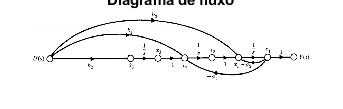

figure
imshow("diagrama_fluxo_item2.png")
title('Diagrama de fluxo')

A partir do diagrama de fluxo, obtem-se o sistema de equações diferenciais de primeira ordem:


$$\dot{x_1}=-a_2x_1+x_2+b_2u$$
                     
$$\dot{x_2}=-a_1x_1+x_3+b_1u$$
                     
$$\dot{x_3}=b_0u$$


Portanto as matrizes A, B, C e D serão:

global F A B 
A = [-a2 1 0; -a1 0 1; 0 0 0];
B = [b2; b1; b0];
C = [1 0 0];
D = 0;


A confirmação de que o métodos foi feito corretamente pode se dar utilizando o comando ss2tf e encontrando a mesma função transferencia usada no processo inicial:

[num,den] = ss2tf(A,B,C,D);
tf(num,den)

ans =
 
  38.84 s^2 + 1685 s + 1.015e04
  -----------------------------
    s^3 + 16.27 s^2 + 31.82 s
 
Continuous-time transfer function.



#### Realimentando o sistema utilizando como referência o código simulaviao.m

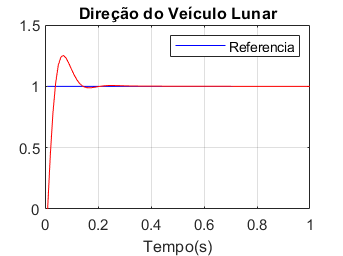

% vetor estados inicial
Xs = [0 0 0];  
F = 0;

% Inicialização de variáveis
tfinal = 1; % Tempo total de simulação
ref = 1; % Referência
passo = 0;
tempo = 0;
dT = 0.01; % tempo de amostragem

while (tempo < tfinal)
    
    passo = passo + 1;   
    ts = passo*dT;
    
    % simulação da equação diferencial
    [T1,X] = ode45('modelo_linear3',[tempo ts], Xs);
    
    % Armazenamento de variaveis
    n = length(T1);
    tempo = ts;
    Xs = X(n,:);
    F = ref-C*Xs';
    
    vetout(passo,:) = [X(n,1) X(n,2) X(n,3)];
    vettime(passo) = T1(n,:);
    vetvref(passo,:) = ref;

end

% Plotagem dos gráficos
figure
plot(vettime, vetvref,'b');
hold on;
plot(vettime,vetout(:,1),'r');
xlabel('Tempo(s)');title('Direção do Veículo Lunar');
legend('Referencia');
grid;

y = vetout(:,1);
stepinfo(y,vettime)

ans = struct with fields:
         RiseTime: 0.0226
    TransientTime: 0.1325
     SettlingTime: 0.1325
      SettlingMin: 0.9879
      SettlingMax: 1.2523
        Overshoot: 25.2273
       Undershoot: 0
             Peak: 1.2523
         PeakTime: 0.0700


**Caso 2. Adicionar ruído Gaussiano na saída do sistema de controle, referente ao sensor do veículo lunar.**

Para simular com ruído, adicionamos à saída o ruído utilizando o comando rand, dessa forma o valor realimentado no processo será alterado.

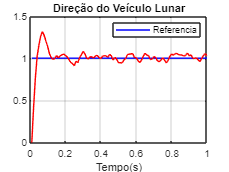

% vetor estados inicial
Xs = [0 0 0];  
F = 0;

% Inicialização de variáveis
tfinal = 1; % Tempo total de simulação
ref = 1; % Referência
passo = 0;
tempo = 0;
dT = 0.01; % tempo de amostragem

while (tempo < tfinal)
    
    passo = passo + 1;   
    ts = passo*dT;
    
    % simulação da equação diferencial
    [T1,X] = ode45('modelo_linear3',[tempo ts], Xs);
    
    % Armazenamento de variaveis
    n = length(T1);
    tempo = ts;
    Xs = X(n,:);
    F = ref-(C*Xs'-0.1+(0.1+0.1)*rand(1));
    
    vetout(passo,:) = [X(n,1) X(n,2) X(n,3)];
    vettime(passo) = T1(n,:);
    vetvref(passo,:) = ref;

end

% Plotagem dos gráficos
figure
plot(vettime, vetvref,'b');
hold on;
plot(vettime,vetout(:,1),'r');
xlabel('Tempo(s)');title('Direção do Veículo Lunar');
legend('Referencia');
grid;

#### 2.3 Compare a resposta ao degrau obtida usando o simulador desenvolvido no item 1.2 (sem o ruído de medição), com a resposta ao degrau (sobressinal, tempo de subida) obtida no item 1.1 para T=0 s.

#### 2.4 Controlador Avanço-Atraso

### Caso 1: T=0

#### Etapa 1: Determinar ganho k1 para atender as especificações do erro em regime e da largura de banda  

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
T = 0;
nps = poly2sym(np,s);
dps = poly2sym(dp,s);
gps = nps/dps;
    % Entrada degrau
sEs = 1/(1+gps);
ess = double(limit(sEs,s,0,'right'));
    % Disturbio degrau
sEd = gps/(1+gps);
essd = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------
% 20*log(Kp) pelo gráfico de bode vale 30.8 dB. 
Kp = 10^(30.8/20)

Kp = 34.6737

ess = 1/(Kp+1) % erro em regime ao degrau sistema tipo 0

ess = 0.0280

Com o aumento de K, diminui o erro em regime a entrada e a margem de fase. O erro ao disturbio será reduzido em passos adiante quando pudermos aumentar a margem de fase.

% Calculo de k para atender erro em regime
syms k_at

sEs = 1/(1+k_at*gps);
eq = limit(sEs,s,0,'right') == 0.1;
k_atraso = double(solve(eq))

k_atraso = 0.2603

sEd = gps/(1+k_at*gps);
eq = limit(sEd,s,0,'right') == 0.1;
k_atraso = double(solve(eq))

k_atraso = 9.9711

k_atraso = 12;
%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)

    % Entrada degrau
sEs = 1/(1+k_atraso*gps);
ess(1) = double(limit(sEs,s,0,'right'))

ess = 0.0024

    % Disturbio degrau
sEd = gps/(1+k_atraso*gps);
essd(1) = double(limit(sEd,s,0,'right'))

essd = 0.0831

%-------------------------------------------------------------------------------------------------

#### Etapa 2: Projetar o controlador atraso de fase  

    Passo 2: MG, MF, frequências de cruzamento de ganho e de fase e a largura de banda

[Gm,Pm,Wgm,Wpm]=margin(k_atraso*gp);
Pm

Pm = 8.1116

Wpm

Wpm = 114.4503

% MF de gp = 8.11 e largura de banda = 114.45


    Passo 3: Nova frequência de cruzamento de ganho

FaseGp = 20 - 180

FaseGp = -160

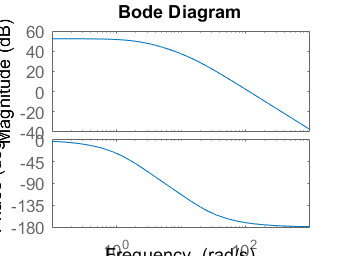

figure
bode(k_atraso*gp)

% Olhando no gráfico de bode, a nova frequencia de cruzamento de ganho (w_0dB)
% deve ser 46.05 rad/s e o módulo nessa frequência é 15,5.
mod = 15.5;


    Passo 4: Obter a constante alpha resolvendo a equação

syms alpha1
eq = 20*log10(mod) + 20*log10(alpha1);
alpha1 = double(solve(eq))

alpha1 = 0.0645

    Passo 5: Escolher a frequência de corte do zero do compensador uma década abaixo (46.06/10 = 4.6) da nova frequência de cruzamento de ganho e  encontrar a frequência de corte do polo do compensador

syms tau1
eq = 1/(alpha1*tau1) - 4.6;
tau1 = double(solve(eq))

tau1 = 3.3696

1/(alpha1*tau1) % freq de corte do zero do compensador

ans = 4.6000

1/(tau1) % freq de corte do polo do compensador

ans = 0.2968

syms jw
g_atrasos = k_atraso*(1+jw*alpha1*tau1)/(1+jw*tau1);

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
g_atrasos = subs(g_atrasos,jw,s);
    % Entrada degrau
sEs = 1/(1+g_atrasos*gps);
ess(1) = double(limit(sEs,s,0,'right'));

    % Disturbio degrau
sEd = gps/(1+g_atrasos*gps);
essd(1) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------
[num,den]=numden(g_atrasos);
g_atraso = tf(sym2poly(num),sym2poly(den))

g_atraso =
 
  120 s + 552
  -----------
  155 s + 46
 
Continuous-time transfer function.



#### Etapa 3:

gma_linha = g_atraso * gp;
[Gm,Pm1,Wgm,Wpm]=margin(gma_linha)

Gm = Inf

Pm1 = 22.6808

Wgm = Inf

Wpm = 27.7109

gmf_linha = feedback(gma_linha,1);
y1 = 0;
t=0:.001:1;
y1 = step(gmf_linha,t);
% Margem de fase alcançada foi de 22.68

#### Etapa 4:

k_avanco = 1;
FaseGma = 70 - Pm1; % margem de fase especificada 60, +10 de folga
syms alpha2
eq=(alpha2-1)/(2*sqrt(alpha2))==tand(FaseGma);
alpha2 = double(solve(eq))

alpha2 = 6.5512

% 5:
mod = -10*log10(alpha2)

mod = -8.1632

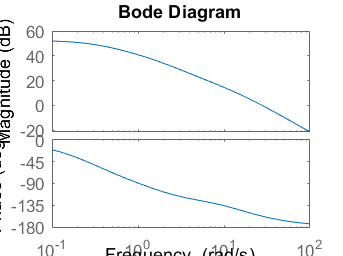

figure
bode(gma_linha,w)

% Olhando no diagrama de Bode, wm será 45,5 rad/s.
wm = 45.5;
% 6:
tau2 = 1/(wm*sqrt(alpha2));
1/(alpha2*tau2) % freq de corte do zero do compensador

ans = 17.7767

1/(tau2) % freq de corte do polo do compensador

ans = 116.4588

g_avancos = k_avanco*(1+jw*alpha2*tau2)/(1+jw*tau2);

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
g_avancos = subs(g_avancos,jw,s);
    % Entrada degrau
sEs = 1/(1+g_avancos*g_atrasos*gps);
ess(2) = double(limit(sEs,s,0,'right'));

    % Disturbio degrau
sEd = gps/(1+g_avancos*g_atrasos*gps);
essd(2) = double(limit(sEd,s,0,'right'));
%-------------------------------------------------------------------------------------------------

[num,den]=numden(g_avancos);
g_avanco = tf(sym2poly(num),sym2poly(den))

g_avanco =
 
  9.128e30 s + 1.623e32
  ---------------------
  1.393e30 s + 1.623e32
 
Continuous-time transfer function.



gma = g_avanco * g_atraso * gp;
[Gm,Pm,Wgm,Wpm]=margin(gma)

Gm = Inf

Pm = 61.7659

Wgm = Inf

Wpm = 45.8888

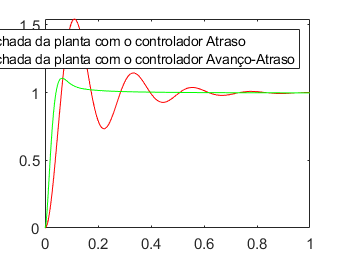

gmf = feedback(gma,1);
up5(2) = stepinfo(gmf).Overshoot; %vetor para questão 5
tr5(2) = stepinfo(gmf).RiseTime;  %vetor para questão 5
t=0:.001:1;
y2 = 0;
y2 = step(gmf,t);
%-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-
% Plots
figure
plot(t,y1,'r',t,y2,'g')
axis([0 1 0 inf])
legend('Malha fechada da planta com o controlador Atraso','Malha fechada da planta com o controlador Avanço-Atraso');



MG=0;MF=0;LB=0;OS=0;RT=0;ST=0;
[Gm,Pm,Wgm,Wpm]=margin(gma_linha);
MG(1) = Gm;
MF(1) = Pm;
LB(1) = bandwidth(gmf_linha);
OS(1)=stepinfo(gmf_linha).Overshoot;
RT(1)=stepinfo(gmf_linha).RiseTime;
ST(1)=stepinfo(gmf_linha).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gma);
MG(2) = Gm;
MF(2) = Pm;
LB(2) = bandwidth(gmf);
OS(2)=stepinfo(gmf).Overshoot;
RT(2)=stepinfo(gmf).RiseTime;
ST(2)=stepinfo(gmf).SettlingTime;

col_atraso = [OS(1) RT(1) ess(1) essd(1) MG(1) MF(1) LB(1)]';
col_avancoatraso = [OS(2) RT(2) ess(2) essd(2) MG(2) MF(2) LB(2)]';
col_avancoatraso_nodelay = col_avancoatraso;
Tabela1=table(col_atraso,col_avancoatraso,'RowNames',{'Sobressinal (%)','T. Subida (s)','Erro à entrada degrau','Erro ao disturbio de degrau','MG','MF','LB'},'VariableNames',{'Gp*Atraso','Gp*Avanço-Atraso'})

Tabela1 = 7×2 table
                                   Gp*Atraso    Gp*Avanço-Atraso
                                   _________    ________________

    Sobressinal (%)                   54.578          10.882    
    T. Subida (s)                   0.041264        0.027841    
    Erro à entrada degrau          0.0024047       0.0024047    
    Erro ao disturbio de degrau     0.083133        0.083133    
    MG                                   Inf             Inf    
    MF                                22.681          61.766    
    LB                                 43.82          72.366    


### Caso 2: T=0.1/N

#### Etapa 1: Determinar ganho k1 para atender as especificações do erro em regime e da largura de banda

% bode(gpd)
% 20*log(Kp) pelo gráfico de bode vale 30.8 dB. 
%----------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
T = 0.1/N; %Caso 1: T=0 | Caso 2: T=0.1/N
nps = poly2sym(np,s)*exp(-T*s);
dps = poly2sym(dp,s);
gps = nps/dps;
    % Entrada degrau
sEs = 1/(1+gps);
ess = double(limit(sEs,s,0,'right'))

ess = 0.0281

    % Disturbio degrau
sEd = gps/(1+gps);
essd = double(limit(sEd,s,0,'right'))

essd = 0.9719

%----------------------------------------------------------------------------------------------
% Com o aumento de K, diminui o erro em regime e a margem de fase e aumenta a largura de banda.

% Calculo de k para atender erro em regime
syms k_at

sEs = 1/(1+k_at*gps);
eq = limit(sEs,s,0,'right') == 0.1;
k_atraso = double(solve(eq))

k_atraso = 0.2603

sEd = gps/(1+k_at*gps);
eq = limit(sEd,s,0,'right') == 0.1;
k_atraso = double(solve(eq))

k_atraso = 9.9711

Escolhe-se o k_atraso de 10 pois a margem de fase da planta já é muito baixa, quanto maior o K escolhido, piorará ainda mais a margem de fase e ficará dificil de compensar depois no estágio de avanço. Com k_atraso = 10, temos o máximo de erro ao disturbio permitido.

k_atraso = 10;

%-------------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
    % Entrada degrau
sEs = 1/(1+k_atraso*gps);
ess(1) = double(limit(sEs,s,0,'right'))

ess = 0.0029

    % Disturbio degrau
sEd = gps/(1+k_atraso*gps);
essd(1) = double(limit(sEd,s,0,'right'))

essd = 0.0997

%-------------------------------------------------------------------------------------------------

#### Etapa 2: Projetar o controlador atraso de fase  

Passo 2: MG, MF, frequências de cruzamento de ganho e de fase e a largura de banda

[Gm,Pm,Wgm,Wpm]=margin(k_atraso*gpd);

Pm

Pm = -45.4932

Wpm

Wpm = 104.3986

% MF de gp = -45.5 e largura de banda = 104.4

Apenas com o k no sistema, ele fica instavel.

Passo 3: Nova frequência de cruzamento de ganho

FaseGp = 20 - 180

FaseGp = -160

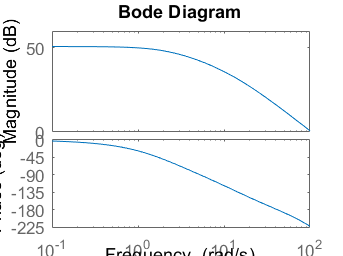

figure
bode(k_atraso*gpd,w)

% Olhando no gráfico de bode, a nova frequencia de cruzamento de ganho (w_0dB)
% deve ser 25.9 rad/s e o módulo nessa frequência é 23.1.
mod = 23.1;

Passo 4: Obter a constante alpha resolvendo a equação

syms alpha1
eq = 20*log10(mod) + 20*log10(alpha1);
alpha1 = double(solve(eq))

alpha1 = 0.0433

Passo 5: Escolher a frequência de corte do zero do compensador uma década abaixo (23.1/10 = 2.31) da nova frequência de cruzamento de ganho e  encontrar a frequência de corte do polo do compensador

syms tau1
eq = 1/(alpha1*tau1) - 2.31;
tau1 = double(solve(eq))

tau1 = 10

1/(alpha1*tau1) % freq de corte do zero do compensador

ans = 2.3100

1/(tau1) % freq de corte do polo do compensador

ans = 0.1000

syms jw
g_atrasos = k_atraso*(1+jw*alpha1*tau1)/(1+jw*tau1);
%----------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
g_atrasos = subs(g_atrasos,jw,s);
% Entrada degrau
sEs = 1/(1+g_atrasos*gps);
ess(1) = double(limit(sEs,s,0,'right'));
% Disturbio degrau
sEd = gps/(1+g_atrasos*gps);
essd(1) = double(limit(sEd,s,0,'right'));
%----------------------------------------------------------------------------------------------
[num,den]=numden(g_atrasos);
g_atraso = tf(sym2poly(num),sym2poly(den))

g_atraso =
 
  1000 s + 2310
  -------------
  2310 s + 231
 
Continuous-time transfer function.



#### Etapa 3:

gmad_linha = g_atraso * gpd;
[Gm,Pm1,Wgm,Wpm]=margin(gmad_linha)

Gm = 3.3157

Pm1 = 25.3141

Wgm = 38.5231

Wpm = 19.7044

% Margem de fase alcançada foi de 25.31
gmfd_linha = feedback(gmad_linha,1);
y1 = 0;
t=0:.001:2;
y1 = step(gmfd_linha,t);

#### Etapa 4:

k_avanco = 1;
FaseGma = 70 - Pm1; % margem de fase especificada 60, +10 de folga
syms alpha2
eq=(alpha2-1)/(2*sqrt(alpha2))==tand(FaseGma);
alpha2 = double(solve(eq))

alpha2 = 5.7390

% 5:
mod = -10*log10(alpha2)

mod = -7.5883

figure
bode(gma_linha,w)

% Olhando no diagrama de Bode, wm será 44.14 rad/s.
wm = 44.14;
% 6:
tau2 = 1/(wm*sqrt(alpha2));
1/(alpha2*tau2) % freq de corte do zero do compensador

ans = 18.4253

1/(tau2) % freq de corte do polo do compensador

ans = 105.7425

g_avancos = k_avanco*(1+jw*alpha2*tau2)/(1+jw*tau2);
%----------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
g_avancos = subs(g_avancos,jw,s);
% Entrada degrau
sEs = 1/(1+g_avancos*g_atrasos*gps);
ess(2) = double(limit(sEs,s,0,'right'));
% Disturbio degrau
sEd = gps/(1+g_avancos*g_atrasos*gps);
essd(2) = double(limit(sEd,s,0,'right'));
%----------------------------------------------------------------------------------------------
[num,den]=numden(g_avancos);
g_avanco = tf(sym2poly(num),sym2poly(den))

g_avanco =
 
  1.761e31 s + 3.245e32
  ---------------------
  3.069e30 s + 3.245e32
 
Continuous-time transfer function.



gmad = g_avanco * g_atraso * gpd;
[Gm,Pm,Wgm,Wpm]=margin(gmad)

Gm = 4.5357

Pm = 54.9094

Wgm = 90.0256

Wpm = 26.9281

gmfd = feedback(gmad,1);
t=0:.001:2;
y2 = 0;
y2 = step(gmfd,t);


#### Refazendo o controlador pois a margem de fase obtida não atendeu a especificação de margem de fase:

k_avanco = 1;
FaseGma = 80 - Pm1; % margem de fase especificada 60, +20 de folga
syms alpha2
eq=(alpha2-1)/(2*sqrt(alpha2))-tand(FaseGma);
alpha2 = double(solve(eq))

alpha2 = 9.8693

% 5:
mod = -10*log10(alpha2)

mod = -9.9428

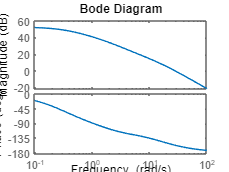

figure
bode(gma_linha,w)


% Olhando no diagrama de Bode, para mod = -9.94, wm será 50.85 rad/s.
wm = 50.85;
% 6:
tau2 = 1/(wm*sqrt(alpha2));
1/(alpha2*tau2) % freq de corte do zero do compensador

ans = 16.1863

1/(tau2) % freq de corte do polo do compensador

ans = 159.7472

g_avancos = k_avanco*(1+jw*alpha2*tau2)/(1+jw*tau2);
%----------------------------------------------------------------------------------------------
% Calculo do erro em regime (s -> 0)
g_avancos = subs(g_avancos,jw,s);
% Entrada degrau
sEs = 1/(1+g_avancos*g_atrasos*gps);
ess(3) = double(limit(sEs,s,0,'right'));
% Disturbio degrau
sEd = gps/(1+g_avancos*g_atrasos*gps);
essd(3) = double(limit(sEd,s,0,'right'));
%----------------------------------------------------------------------------------------------
[num,den]=numden(g_avancos);
g_avanco = tf(sym2poly(num),sym2poly(den))

g_avanco =
 
  2.005e31 s + 3.245e32
  ---------------------
  2.031e30 s + 3.245e32
 
Continuous-time transfer function.



gmad2 = g_avanco * g_atraso * gpd;
[Gm,Pm,Wgm,Wpm]=margin(gmad2)

Gm = 4.3184

Pm = 60.6942

Wgm = 106.1266

Wpm = 29.7911

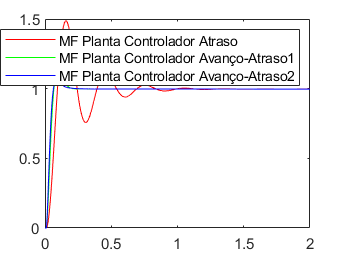

gmfd2 = feedback(gmad2,1);
t=0:.001:2;
y3 = 0;
y3 = step(gmfd2,t);

%-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_-_
% Plots
figure
plot(t,y1,'r',t,y2,'g',t,y3,'b')
legend('MF Planta Controlador Atraso','MF Planta Controlador Avanço-Atraso1','MF Planta Controlador Avanço-Atraso2')


MG=0;MF=0;LB=0;OS=0;RT=0;ST=0;
[Gm,Pm,Wgm,Wpm]=margin(gmad_linha);
MG(1) = Gm;
MF(1) = Pm;
LB(1) = bandwidth(gmfd_linha);
OS(1)=stepinfo(gmfd_linha).Overshoot;
RT(1)=stepinfo(gmfd_linha).RiseTime;
ST(1)=stepinfo(gmfd_linha).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gmad);
MG(2) = Gm;
MF(2) = Pm;
LB(2) = bandwidth(gmfd);
OS(2)=stepinfo(gmfd).Overshoot;
RT(2)=stepinfo(gmfd).RiseTime;
ST(2)=stepinfo(gmfd).SettlingTime;

[Gm,Pm,Wgm,Wpm]=margin(gmad2);
MG(3) = Gm;
MF(3) = Pm;
LB(3) = bandwidth(gmfd2);
OS(3)=stepinfo(gmfd2).Overshoot;
RT(3)=stepinfo(gmfd2).RiseTime;
ST(3)=stepinfo(gmfd2).SettlingTime;

% Reorganização de dados
col_atraso = [OS(1) RT(1) ess(1) essd(1) MG(1) MF(1) LB(1)]';
col_avancoatraso = [OS(2) RT(2) ess(2) essd(2) MG(2) MF(2) LB(2)]';
col_avancoatraso2 = [OS(3) RT(3) ess(3) essd(3) MG(3) MF(3) LB(3)]';
Tabela1=table(col_atraso,col_avancoatraso,col_avancoatraso2,'RowNames',{'Sobressinal (%)','T. Subida (s)','Erro à entrada degrau','Erro ao disturbio de degrau','MG','MF','LB'},'VariableNames',{'Gp*Atraso','Gp*Avanço-Atraso','Gp*Avanço-Atraso2'})

Tabela1 = 7×3 table
                                   Gp*Atraso    Gp*Avanço-Atraso    Gp*Avanço-Atraso2
                                   _________    ________________    _________________

    Sobressinal (%)                    49.05          12.861               6.4454    
    T. Subida (s)                   0.056738        0.039492             0.035996    
    Erro à entrada degrau          0.0028842       0.0028842            0.0028842    
    Erro ao disturbio de degrau     0.099712        0.099712             0.099712    
    MG                                3.3157          4.5357               4.3184    
    MF                                25.314          54.909               60.694    
    LB                                32.431          50.945          

#### 2.2 Para o caso em que T=0 seg, multiplique o controlador projetado pela FT G do veículo lunar e determine a equação de estados deste sistema em malha aberta. Em seguida, desenvolva um código no matlab, semelhante ao fornecido para simular o avião (programa “simulaviao.m” fornecido em anexo), para simular o sistema de controle de direção do veículo lunar em malha fechada no espaço de estados. Considere nas simulações os seguintes casos:

#### Caso 1. Sistema de controle sem o ruído de medição.

Usando Avanço-Atraso:

Usando a função transferência de malha aberta encontrada no item 1.1 ao multiplicar o controlador avanço-atraso pela planta:

num = [1.205e36 2.696e37 9.852e37]/3.866e32;
den = [2.16e32 2.873e34 4.246e35 9.237e35 2.375e35]/2.16e32;

gg2 = tf(num,den)

gg2 =
 
      3117 s^2 + 6.974e04 s + 2.548e05
  ----------------------------------------
  s^4 + 133 s^3 + 1966 s^2 + 4276 s + 1100
 
Continuous-time transfer function.



O que se espera após os passos que se seguem é obter uma curva nesse estilo:

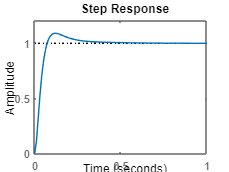

gg2f = feedback(gg2,1);
figure
t=0.0:0.01:1;
step(gg2f,t)

#### Utilizando o modelo de formato de entrada com ação à frente (feedforward):

Usando a função de malha aberta do controlador vezes a G da planta, identificamos seus coeficientes:


$$C(s)G_p(s) = \frac{3117s^2+69740s+254800}{s^4+133s^3+1966s^2+4276s+1100}=\frac{b_2s^2+b_1s+b_0}{s^4+a_3s^3+a_2s^2+a_1s+a_0}$$


b2 = 3117;
b1 = 6.974e04;
b0 = 2.548e05;
a3 = 133;
a2 = 1966;
a1 = 4276;
a0 = 1100;

Para montar o diagrama de fluxo de sinais, dividimos numerador e denominador por $s^4$:


$$C(s)G_p(s) =\frac{b_2s^{-2}+b_1s^{-3}+b_0s^{-4}}{1+a_3s^{-1}+a_2s^{-2}+a_1s^{-3}+a_0s^{-4}}$$


O diagrama de fluxo terá 3 caminhos diretos e 4 loops de realimentação:

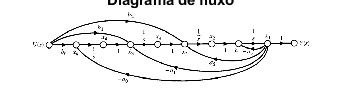

figure
imshow("diagrama_fluxo_item22.png")
title('Diagrama de fluxo')

A partir do diagrama de fluxo, obtem-se o sistema de equações diferenciais de primeira ordem:


$$\dot{x_1}=-a_3x_1+x_2$$
                     
$$\dot{x_2}=-a_2x_1+x_3+b_2u$$
                     
$$\dot{x_3}=-a_1x_1+x_4+b_1u$$
                     
$$\dot{x_4}=-a_0x_1+b_0u$$


Portanto as matrizes A, B, C e D serão:

global F A B 
A = [-a3 1 0 0; -a2 0 1 0; -a1 0 0 1;-a0 0 0 0];
B = [0; b2; b1; b0];
C = [1 0 0 0];
D = 0;


A confirmação de que o métodos foi feito corretamente pode se dar utilizando o comando ss2tf e encontrando a mesma função transferência usada no processo inicial:

[num,den] = ss2tf(A,B,C,D);
tf(num,den)

ans =
 
      3117 s^2 + 6.974e04 s + 2.548e05
  ----------------------------------------
  s^4 + 133 s^3 + 1966 s^2 + 4276 s + 1100
 
Continuous-time transfer function.



#### Realimentando o sistema utilizando como referência o código simulaviao.m

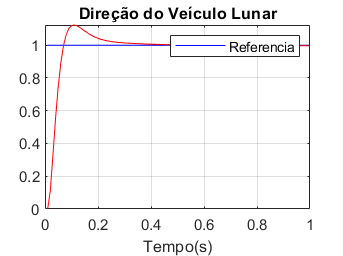

% vetor estados inicial
Xs = [0 0 0 0];  
F = 0;

% Inicialização de variáveis
tfinal = 1; % Tempo total de simulação
ref = 1; % Referência
passo = 0;
tempo = 0;
dT = 0.01; % tempo de amostragem

while (tempo < tfinal)
    
    passo = passo + 1;   
    ts = passo*dT;
    
    % simulação da equação diferencial
    [T1,X] = ode45('modelo_linear',[tempo ts], Xs);
    
    % Armazenamento de variaveis
    n = length(T1);
    tempo = ts;
    Xs = X(n,:);
    F = ref-C*Xs';
    
    vetout(passo,:) = [X(n,1) X(n,2) X(n,3)];
    vettime(passo) = T1(n,:);
    vetvref(passo,:) = ref;

end

% Plotagem dos gráficos
figure
plot(vettime, vetvref,'b');
hold on;
plot(vettime,vetout(:,1),'r');
xlabel('Tempo(s)');title('Direção do Veículo Lunar');
legend('Referencia');
grid;

y = vetout(:,1);
stepinfo(y,vettime)

ans = struct with fields:
         RiseTime: 0.0411
    TransientTime: 0.2821
     SettlingTime: 0.2821
      SettlingMin: 0.9963
      SettlingMax: 1.1233
        Overshoot: 12.7497
       Undershoot: 0
             Peak: 1.1233
         PeakTime: 0.1100


#### Caso 2. Adicionar ruído Gaussiano na saída do sistema de controle, referente ao sensor do veículo lunar.

Para simular com ruído, adicionamos à saída o ruído utilizando o comando rand, dessa forma o valor realimentado no processo será alterado.

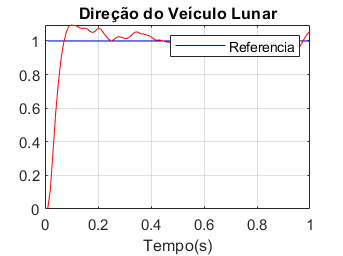

% vetor estados inicial
Xs = [0 0 0 0];  
F = 0;

% Inicialização de variáveis
tfinal = 1; % Tempo total de simulação
ref = 1; % Referência
passo = 0;
tempo = 0;
dT = 0.01; % tempo de amostragem

while (tempo < tfinal)
    
    passo = passo + 1;   
    ts = passo*dT;
    
    % simulação da equação diferencial
    [T1,X] = ode45('modelo_linear',[tempo ts], Xs);
    
    % Armazenamento de variaveis
    n = length(T1);
    tempo = ts;
    Xs = X(n,:);
    F = ref-(C*Xs'-0.1+(0.1+0.1)*rand(1));
    
    vetout(passo,:) = [X(n,1) X(n,2) X(n,3)];
    vettime(passo) = T1(n,:);
    vetvref(passo,:) = ref;

end

% Plotagem dos gráficos
figure
plot(vettime, vetvref,'b');
hold on;
plot(vettime,vetout(:,1),'r');
xlabel('Tempo(s)');title('Direção do Veículo Lunar');
legend('Referencia');
grid;

#### 2.5 Compare as respostas à entrada degrau (sobressinal, tempo de subida) e o erro em regime às entradas degrau para os dois sistemas com os controladores obtidos nos itens 1.1 e 1.4 para T=0.0 s.

Tabela1=table(col_PID_nodelay,col_avancoatraso_nodelay,'RowNames',{'Sobressinal (%)','T. Subida (s)','Erro à entrada degrau','Erro ao disturbio de degrau','MG','MF','LB'},'VariableNames',{'Gp*PID','Gp*Avanço-Atraso'})

Tabela1 = 7×2 table
                                   Gp*PID    Gp*Avanço-Atraso
                                   ______    ________________

    Sobressinal (%)                     0          10.882    
    T. Subida (s)                  0.0116        0.027841    
    Erro à entrada degrau               0       0.0024047    
    Erro ao disturbio de degrau         0        0.083133    
    MG                                Inf             Inf    
    MF                              90.53          61.766    
    LB                             191.69          72.366    


A função de transferência que descreve a dinâmica do veículo lunar sem atraso e sem ruído de medição, foi submetida a dois controladores diferentes (PID e Avanço-Atraso) e projetados para que os erros a entrada ao degrau e os erros ao distúrbio ao degrau fossem menores que 0.1, A largura de banda em malha aberta fosse a maior possível e a margem de fase igual ou superior a 60º.

Considerando o erro entrada ao degrau, ambos atenderam às condições de projeto. Ess < 0.1

PID: 0

AA: 0.0024

Considerando o erro ao distúrbio de degrau, ambos atenderam às condições de projeto. Edss < 0.1

PID: 0

AA: 0.0831

Considerando a margem de fase, ambos atenderam às condições de projeto. MF >= 60º

PID: 90.53º

AA: 61.76º

E a largura de Banda foi a maior possível, consideradno as condições de projetos acima.

PID: 191.68

AA: 72.36

Levando em conta todos os parâmetros e características acima, o controlador PID é o que obteve melhor resultado, onde além de apresentar os pontos acima, teve um melhor tempo de subida e tambem melhor sobreelevação.

#### **2.6 – Considerando o item 2.5, escolha o melhor controlador obtido e determine os polos da FT em malha fechada. A partir destes polos, projete um controlador usando a realimentação de estados para controlar a dinâmica deste sistema.**

No item 2.5 foi realizado uma comparação entre os dois controladores projetados, PID e Avanço-Atraso, para a função Gp, que modela a dinâmica do veículo lunar, sem atraso de transporte. Considerando a resposta ao degrau de cada controlador e da planta, o que obteve melhor resultado foi o PID.

#### Etapa 1. Pólos da FTMF - Gma = Gc*Gp.

A função de transferência utilizada, destacada no enunciado é utilizando a função de malha aberta que multiplica o controlador PID (Gc6) e a função de transferência da planta (Gp). Utilizando essa nova função, fechamos a malha com realimentação negativa e aplicamos o comando pole, para obter os 3 pólos da FTMF, que nesse caso é de ordem 3.

gp;     %planta sem atraso de transporte
gc6;    %Controlador PID
gmf = feedback(gc6*gp,1)        %FTMF ordem 3

gmf =
 
     194.2 s^2 + 2808 s + 1.015e04
  -----------------------------------
  s^3 + 210.5 s^2 + 2840 s + 1.015e04
 
Continuous-time transfer function.



pmf = pole(gmf)

pmf = 	1.0e+02 *

  -1.9628 + 0.0000i
  -0.0710 + 0.0113i
  -0.0710 - 0.0113i


#### Etapa 2. Obter a Matriz de EE na Forma Canônica Controlável, A partir de Gma = Gp.

A etapa 2 é transformar a função de transferência da planta (Gp) em uma matriz de estados, na forma canônica controlável (FCC). Tal etapa é necessário para que possamos realizar a realimentação de estados, usando a forma padrão FCC.

global A B F
[A B C D] = tf2ss(gp.num{1},gp.den{1})

A =   -16.2727  -31.8182
    1.0000         0


B =      1
     0


C =            0        1100


D = 0

O comando "tf2ss" converte uma função de transferência nas matrizes de estado, (A, B, C, e D), já na forma canônica controlável.

#### Etapa 3. Aproximação da FTMF para Ordem 2

Como a função de de transferência de malha fechada é de ordem 3, ou seja, existem 3 pólos, e como a função de malha aberta da planta (Gp) é de ordem 2. Faz-se neessário compatibilizar o número de estados da matriz com o número de realimentaões dos estados, à partir dos pólos de malha fechada. A próxima etapa é aproximar a função de malha fechada da planta e controlador (Gmf) de ordem 3, para uma similar de ordem 2, com os mesmos parâmetros de resposta ao degrau.

up = stepinfo(gmf).Overshoot;
tr = stepinfo(gmf).RiseTime;
% ts = stepinfo(gmf).SettlingTime; % tempo de subida = 0.022
ts = 0.01;
zeta = 0.9;      % como o sistema está no limiar da sobreelevação, zeta = 1 aproximadamente
wn=4/(ts*zeta);        %considerando 2% para assentamento
gap = tf(wn^2,[1 2*zeta*wn wn^2])       % função aproximada

gap =
 
         1.975e05
  ----------------------
  s^2 + 800 s + 1.975e05
 
Continuous-time transfer function.



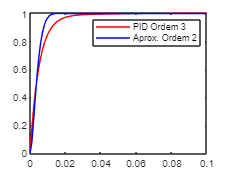

t=0.0:0.001:7;
y1 = step(gmf,t);
y2 = step(gap,t);
repgap(1) = stepinfo(gap).Overshoot;
repgap(2) = stepinfo(gap).RiseTime;
repgap(3) = stepinfo(gap).SettlingTime;


figure
plot(t,y1,'r',t,y2,'b')
axis([0 0.1 0 inf])
legend('PID Ordem 3','Aprox. Ordem 2')

Com respostas bem parecidas, extraimos os novos pólos, para a realimentação de estados.

pmf = pole(gap);                         % novos polos para função de ordem 2

#### Etapa 4. Realimentação de Estados

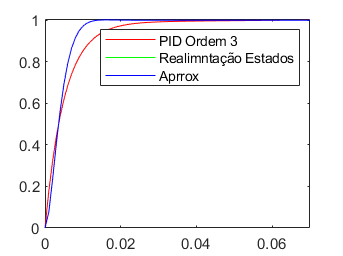

K=place(A,B,pmf);

% clear vetout
% Xs = [0 0];
% F = 0;
% % Inicialização de variáveis
% tfinal = 8; % Tempo total de simulação
% trand = 0;
% ref = 1; % Referência
% passo = 0;
% tempo = 0;
% dT = 0.01; % tempo de amostragem
% ise = 0;
% t2 = 0;
% t1 =0;
% while (tempo < tfinal)
% 
%  passo = passo + 1;
%  ts = passo*dT;
% % simulação da equação diferencial
%  [T1,X] = ode45('modelo_linear2',[tempo ts], Xs);
% % Armazenamento de variaveis
%  n = length(T1);
%  tempo = ts;
%  Xs = X(n,:);
%  F = ref-K*(Xs)';
%  
%  vetF(passo,:) = F;
%  vetout(passo,:) = [X(n,1) X(n,2)];
%  vettime(passo) = T1(n,:);
%  vetvref(passo,:) = ref;
% end
% 
% m=ss(A-B*K,B,C,D); % FT de MF
% p1 = 1/freqresp(m,0);
% 
% Y = p1*vetout*C';
% % Plotagem dos gráficos
% f = figure('name','Controle Ótimo Quadrático');
% hold on;
% plot(vettime, vetvref,'b');
% hold on;
% plot(vettime, Y','r');
% xlabel('Tempo(s)');title('Saída do sistema');
% legend('Referencia');
% grid;
% hold off;


m=ss(A-B*K,B,C,D); % FT de MF
y3 = step(m,t);
ref=1/mean(y3(end-10:end));
y3 = step(ref*m,t);
figure
plot(t,y1,'r',t,y3,'g',t,y2,'b')
axis([0 0.07 0 inf])
legend('PID Ordem 3','Realimntação Estados','Aprrox')

repm(1) = stepinfo(m).Overshoot;
repm(2) = stepinfo(m).RiseTime;
repm(3) = stepinfo(m).SettlingTime;

Tabela2=table(repgap',repm','RowNames',{'Sobressinal (%)','T. Subida (s)','T.Assentamento (s)'},'VariableNames',{'FTMF ordem 2 apx','Realimentação de Estados'})

Tabela2 = 3×2 table
                          FTMF ordem 2 apx    Realimentação de Estados
                          ________________    ________________________

    Sobressinal (%)            0.15237                 0.15237        
    T. Subida (s)            0.0064877               0.0064877        
    T.Assentamento (s)        0.010575                0.010575        


#### 2.7 Compare as respostas ao degrau e o respectivo erro à entrada degrau dos sistemas realimentados projetados no 2.1 e 2.4 para T=0.0 s com o sistema realimentado projetado no item 2.6.